# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 17-Jan-2024 03:54:14

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    featureInputLayer(1,"Name","featureinput_4")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_2","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_7","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_6","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    dropoutLayer(0.5,"Name","dropout_2")
    flattenLayer("Name","flatten_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    featureInputLayer(16384,"Name","featureinput_1")
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_4","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_5","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_8","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_9","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    dropoutLayer(0.5,"Name","dropout_4")
    flattenLayer("Name","flatten_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    featureInputLayer(1,"Name","featureinput_3")
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_3","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_6","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_7","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    dropoutLayer(0.5,"Name","dropout_3")
    flattenLayer("Name","flatten_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    featureInputLayer(1,"Name","featureinput_2")
    convolution2dLayer([3 3],32,"Name","conv_4","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_8","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool_5","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_12","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    dropoutLayer(0.5,"Name","dropout_1")
    flattenLayer("Name","flatten_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,4,"Name","concat")
    fullyConnectedLayer(10,"Name","fc")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"flatten_2","concat/in4");
lgraph = connectLayers(lgraph,"flatten_4","concat/in2");
lgraph = connectLayers(lgraph,"flatten_3","concat/in3");
lgraph = connectLayers(lgraph,"flatten_1","concat/in1");

## Plot Layers

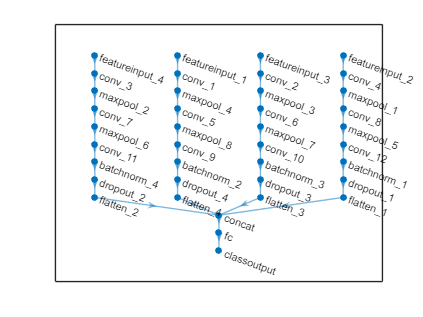

plot(lgraph);